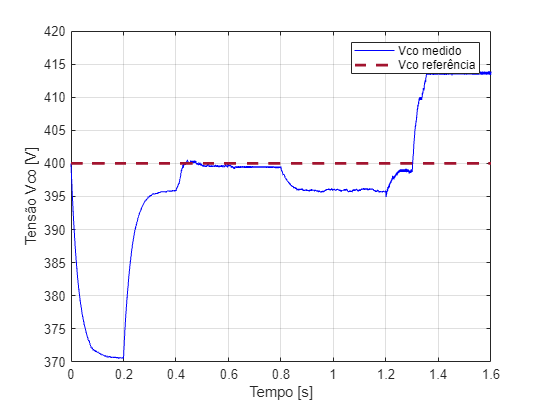

load("resultado Carga sem Kalman.mat")


Vco = out.Vok.signals(1).values;
Vco_ref = out.Vok.signals(2).values;
ILs = out.ILsk.signals(1).values;
ILs_ref = out.ILsk.signals(2).values;
ILb = out.ILbk.signals(1).values;
ILb_ref = out.ILbk.signals(2).values;
t = linspace(0,1.6,length(Vco));

plot(t,Vco,"Color","b","DisplayName","Vco medido")
hold on
plot(t,Vco_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","Vco referência")
hold off
xlabel("Tempo [s]")
ylabel("Tensão Vco [V]")
axis([0 1.6 370 420])
legend
grid

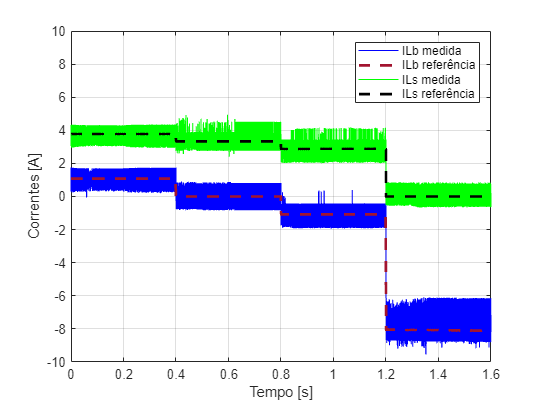


plot(t,ILb,"Color","b","DisplayName","ILb medida")
hold on
plot(t,ILb_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","ILb referência")
plot(t,ILs,"Color","g","DisplayName","ILs medida")
plot(t,ILs_ref,'--','LineWidth',2,"Color","#000000","DisplayName","ILs referência")
hold off
xlabel("Tempo [s]")
ylabel("Correntes [A]")
axis([0 1.6 -10 10])
legend
grid


m1 = Vco(1:40000);
m2 = Vco(40001:80000);
m3 = Vco(80001:120000);
m4 = Vco(120001:160000);

d1 = peak2peak(Vco(1:40000));
d2 = peak2peak(Vco(40001:80000));
d3 = peak2peak(Vco(80001:120000));
d4 = peak2peak(Vco(120001:160000));

disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("400  " +mean(m1)+ "  "+ 100*(mean(m1) - 400)/400 + "  " + d1 + " " + (400 - min(m1)))

400  383.4241  -4.144  29.4957 29.4957


disp("400  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2+ " " + (400  - min(m2)))

400  399.4694  -0.13264  4.717 4.1647


disp("400  " +mean(m3)+ "  "+ 100*(mean(m3) - 400)/400 + "  " + d3+ " " + (400  - min(m3)))

400  396.1538  -0.96155  3.8366 4.3941


disp("400  " +mean(m4)+ "  "+ 100*(mean(m4) - 400)/400 + "  " + d4+ " " + (max(m4)- 400))

400  409.0145  2.2536  19.0847 14.0008



m1 = ILb(1:40000);
m2 = ILb(40001:80000);
m3 = ILb(40001:120000);
m4 = ILb(120001:160000);
d1 = peak2peak(ILb(10000:40000));
d2 = peak2peak(ILb(50001:80000));
d3 = peak2peak(ILb(90001:120000));
d4 = peak2peak(ILb(130001:160000));

disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("1.08  " +mean(m1)+ "  "+ 100*(mean(m1) - 1.08)/1.08 + "  " + d1)

1.08  1.06  -1.8487  1.5447


disp("0  " +mean(m2)+ "  "+ 100*(mean(m2) - 400)/400 + "  " + d2)

0  0.028726  -99.9928  1.702


disp("-1.08  " +mean(m3)+ "  "+ 100*(mean(m3) +1.08)/1.08 + "  " + d3)

-1.08  -0.54811  49.2494  2.3181


disp("-8.03  " +mean(m4)+ "  "+ 100*(mean(m4) +8.03)/8.03 + "  " + d4)

-8.03  -7.7462  3.5337  3.4478



m1 = ILs(1:40000);
m2 = ILs(40001:80000);
m3 = ILs(40001:120000);
m4 = ILs(120001:160000);
d1 = peak2peak(ILs(10000:40000));
d2 = peak2peak(ILs(50001:80000));
d3 = peak2peak(ILs(90001:120000));
d4 = peak2peak(ILs(130001:160000));

disp("REF  " + "Media     " + "EMRP  " + "   Delta ");

REF  Media     EMRP     Delta 


disp("3.78  " +mean(m1)+ "  "+ 100*(mean(m1) - 3.78)/3.78 + "  " + d1)

3.78  3.7208  -1.566  1.4074


disp("3.33  " +mean(m2)+ "  "+ 100*(mean(m2) - 3.33)/3.33 + "  " + d2)

3.33  3.3463  0.48957  2.5384


disp("2.88  " +mean(m3)+ "  "+ 100*(mean(m3) - 2.88)/2.88 + "  " + d3)

2.88  3.0765  6.8224  2.1511


disp("0  " +mean(m4)+ "  "+ 100*(mean(m4) +8.03)/8.03 + "  " + d4)

0  0.012476  100.1554  1.5146
